## Chapter 5: Block Diagram Reductions

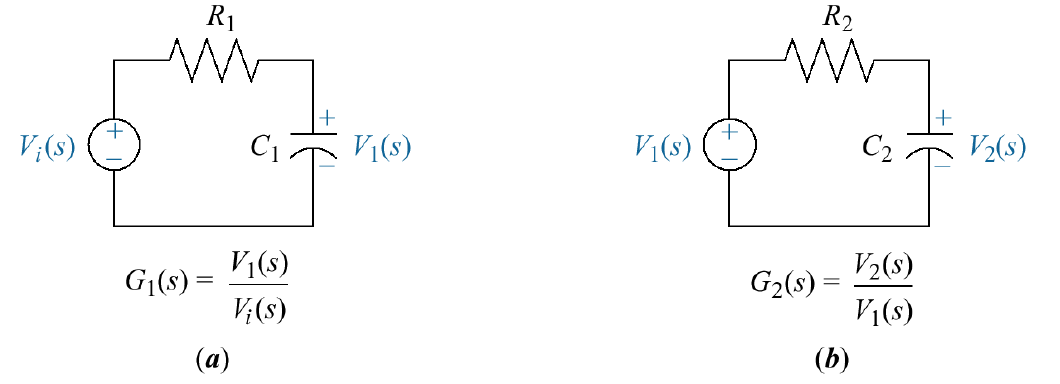

Consider the transfer functions for Fig (a) and (b) above $G_1(s)=\frac{V_1(s)}{V_i(s)}$ and $G_2=\frac{V_2(s)}{V_1(s)}$

clear
syms s Vi R1 C1 R2 C2 V1 V2 I1 I2

You can easily show that 

G1=1/(R1*C1*s+1)

$$G1 = \frac{1}{C_{1}\,R_{1}\,s+1}$$

G2=1/(R2*C2*s+1)

$$G2 = \frac{1}{C_{2}\,R_{2}\,s+1}$$

So you might think that for the circuit shown below, the transfer function $G(s)=\frac{V_2(s)}{V_i(s)}$

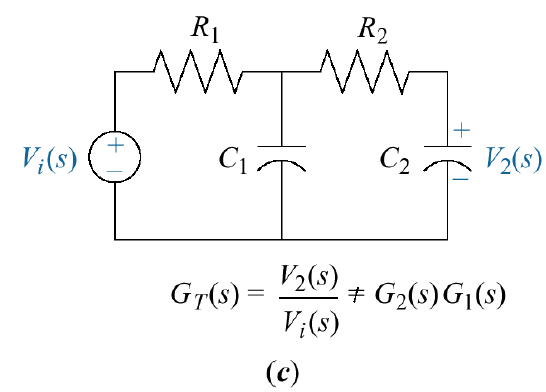

is given by:

G1*G2

$$ans = \frac{1}{\left(C_{1}\,R_{1}\,s+1\right)\,\left(C_{2}\,R_{2}\,s+1\right)}$$

G_Tnoload=collect(ans)

$$G\_Tnoload = \frac{1}{\left(C_{1}\,C_{2}\,R_{1}\,R_{2}\right)\,s^{2}+\left(C_{1}\,R_{1}+C_{2}\,R_{2}\right)\,s+1}$$

But this is ***NOT*** the case due to "loading". In computing the transfer function for circuit (a) $G_1(s)$ in measuring the voltage $V_1(s)$ at its output, we implicitly assume that the current flowing through $R_1$ is the same as the current flowing through $C_1$ but in the combined circuit shown in (c ) if we define the currents flowing left to right through resistors $R_1$and $R_2$ are $I_1$ and $I2$ respectively, we now have that the current flowing through $C_1$ top to bottom is $I_1-I_2$. That change in current caused by the loss of $I_2$ is the "load" placed on the first $G_1(s)$ stage of our cascaded transfer functions. So if sta   


R1*I1+1/(C1*s)*(I1-I2)==Vi 

$$ans = I_{1}\,R_{1}+\frac{I_{1}-I_{2}}{C_{1}\,s}=\mathrm{Vi}$$

eq1=collect(collect(ans,I2),I1)

$$eq1 = \left(R_{1}+\frac{1}{C_{1}\,s}\right)\,I_{1}+\left(-\frac{1}{C_{1}\,s}\right)\,I_{2}=\mathrm{Vi}$$

R2*I2+1/(C2*s)*I2+1/(C1*s)*(I2-I1)==0

$$ans = I_{2}\,R_{2}+\frac{I_{2}}{C_{2}\,s}-\frac{I_{1}-I_{2}}{C_{1}\,s}=0$$

eq2=collect(collect(ans,I2),I1)

$$eq2 = \left(-\frac{1}{C_{1}\,s}\right)\,I_{1}+\left(R_{2}+\frac{1}{C_{1}\,s}+\frac{1}{C_{2}\,s}\right)\,I_{2}=0$$

soln=solve([eq1,eq2],[I1,I2])

soln = struct with fields:
    I1: (Vi*s*(C1 + C2 + C1*C2*R2*s))/(C1*R1*s + C2*R1*s + C2*R2*s + C1*C2*R1*R2*s^2 + 1)
    I2: (C2*Vi*s)/(C1*R1*s + C2*R1*s + C2*R2*s + C1*C2*R1*R2*s^2 + 1)


Note that $I_2(s)\neq 0$

collect(soln.I2)

$$ans = \frac{\left(C_{2}\,\mathrm{Vi}\right)\,s}{\left(C_{1}\,C_{2}\,R_{1}\,R_{2}\right)\,s^{2}+\left(C_{1}\,R_{1}+C_{2}\,R_{1}+C_{2}\,R_{2}\right)\,s+1}$$

V2==1/(C2*s)*soln.I2

$$ans = V_{2}=\frac{\mathrm{Vi}}{C_{1}\,R_{1}\,s+C_{2}\,R_{1}\,s+C_{2}\,R_{2}\,s+C_{1}\,C_{2}\,R_{1}\,R_{2}\,s^{2}+1}$$

G_T=collect(rhs(ans)/Vi)

$$G\_T = \frac{1}{\left(C_{1}\,C_{2}\,R_{1}\,R_{2}\right)\,s^{2}+\left(C_{1}\,R_{1}+C_{2}\,R_{1}+C_{2}\,R_{2}\right)\,s+1}$$

is the actual transfer function whereas the ideal transfer function with no loading is

G_Tnoload

$$G\_Tnoload = \frac{1}{\left(C_{1}\,C_{2}\,R_{1}\,R_{2}\right)\,s^{2}+\left(C_{1}\,R_{1}+C_{2}\,R_{2}\right)\,s+1}$$

So the transfer functions differ by a factor of $C_2R_1s$ in the denominator. So if $R_2>>R_1$(i.e. the input impedance of stage 2 is much bigger than the output impedance of stage 1, then this gets closer to the ideal situation,

**Block DIagram Reduction**

Example from Fig. 5.9

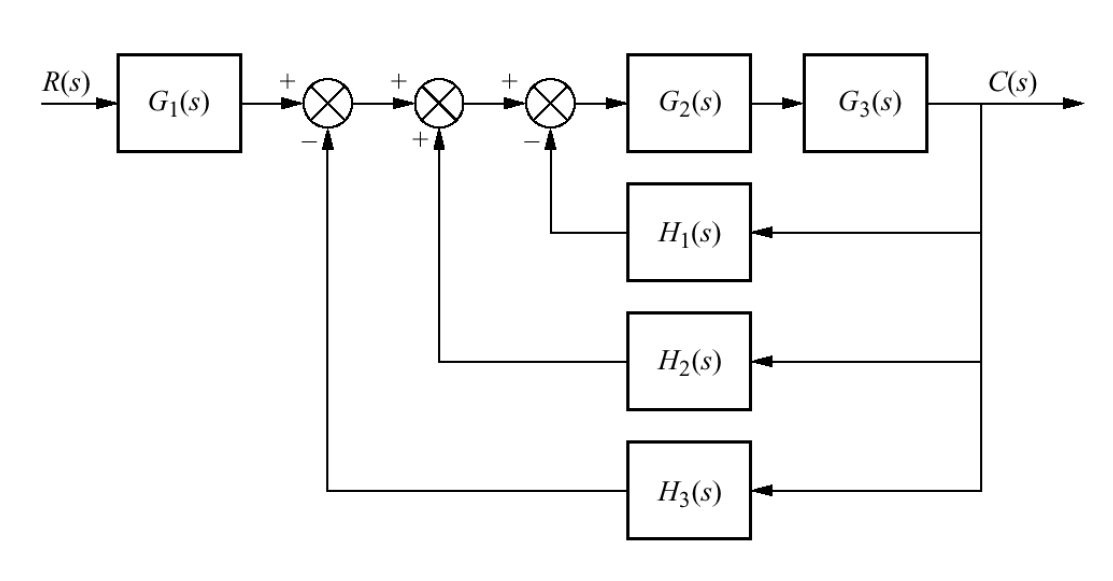

**Method 1:** Verifying step-by-step manual block diagram manipulations

syms G_1 G_2 G_3 H_1 H_2 H_3

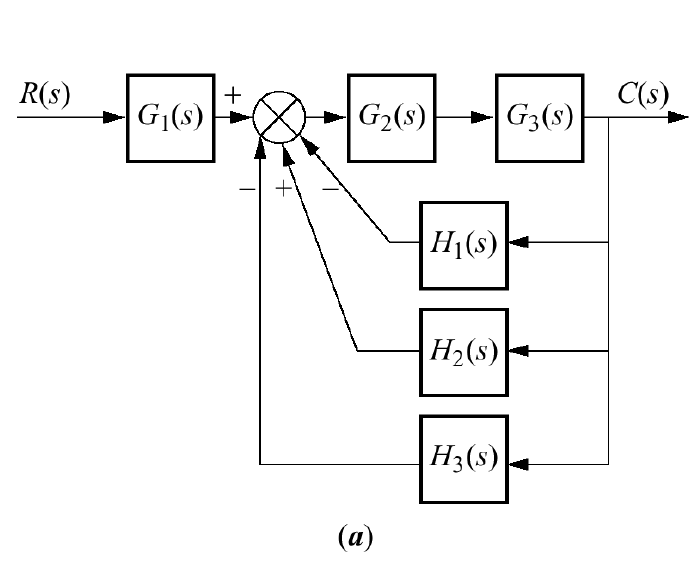

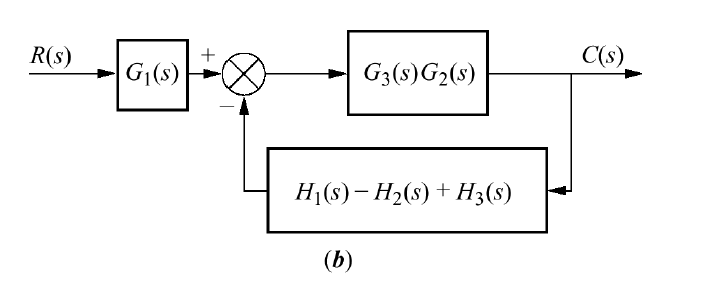

Collapse the feedback loop:

G=G_2*G_3
H=H_1-H_2+H_3
G_collapse=G/(1+G*H)

Now we have $G_1$ in cascade with $G_\textit{collapse}$ so the final equvalent block diagram is:

G_eq=G_1*G_collapse

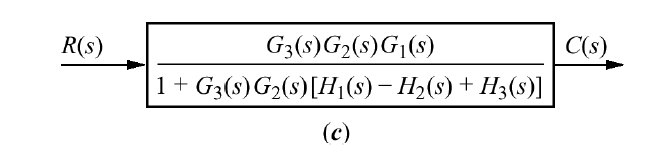

**Method 2**: Define state variables $x_1, x_2, x_3$ at the output of each summing junction and write down equations and solve

syms X_1 X_2 X_3 C R
eq1 = X_1 == G_1*R-H_3*C
eq2 = X_2 == X_1+H_2*C
eq3 = X_3 == X_2-H_1*C
eqC = C == G_2*G_3*X_3
BDsoln=solve([eq1,eq2,eq3,eqC],[X_1,X_2,X_3,C])
G_cl=BDsoln.C/R
%[A,B]=equationsToMatrix([eq1,eq2,eq3,eq4],[X_1,X_2,X_3,X_4])
collect(G_cl-G_eq)
G_cl-G_eq

**Block Diagram Reduction** (20 marks) (From 2020 Midterm)

Consider the block diagram below:

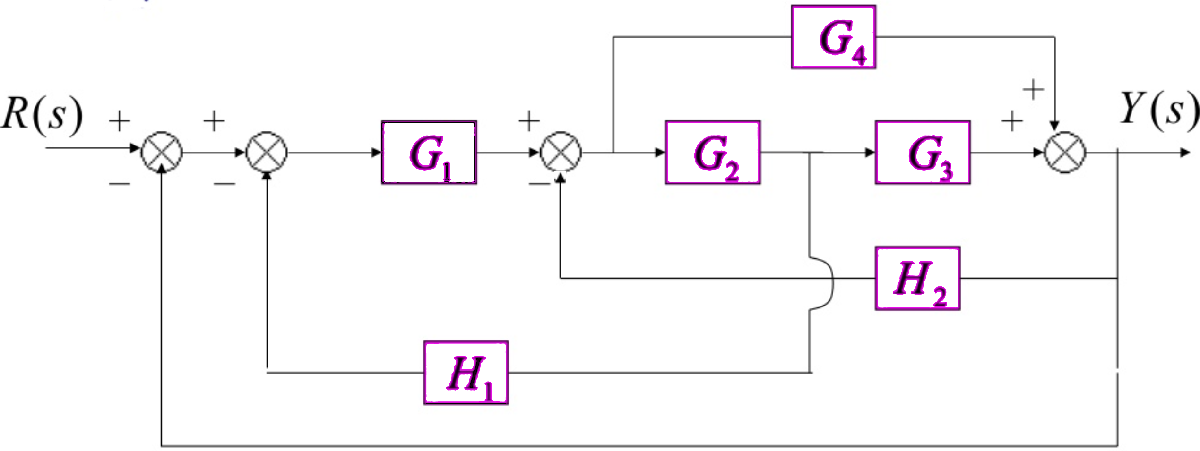

What is the closed loop transfer function $G_{cl}(s)=\frac{Y(s)}{R(s)}$?

Start by moving pickoff point from A to B as shown below:

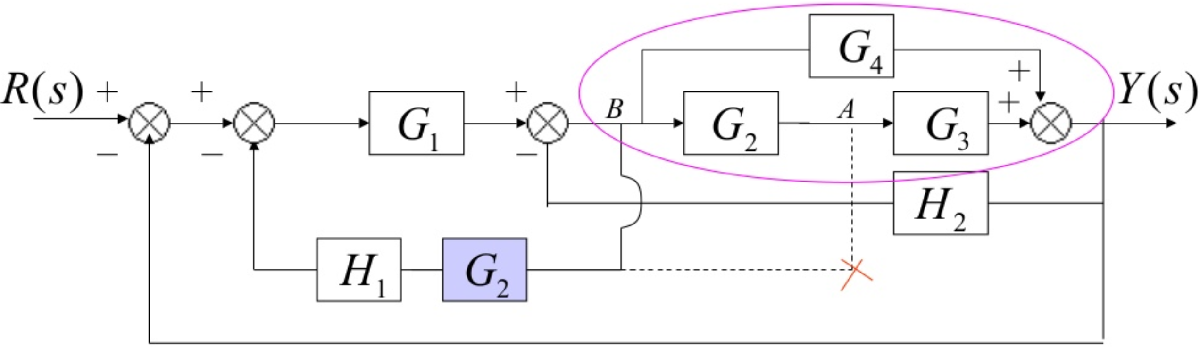

Reduce parallel blocks $G_4||G_2G_3$ and combine sequential blocks $H_1$ and $G_2$ to get:

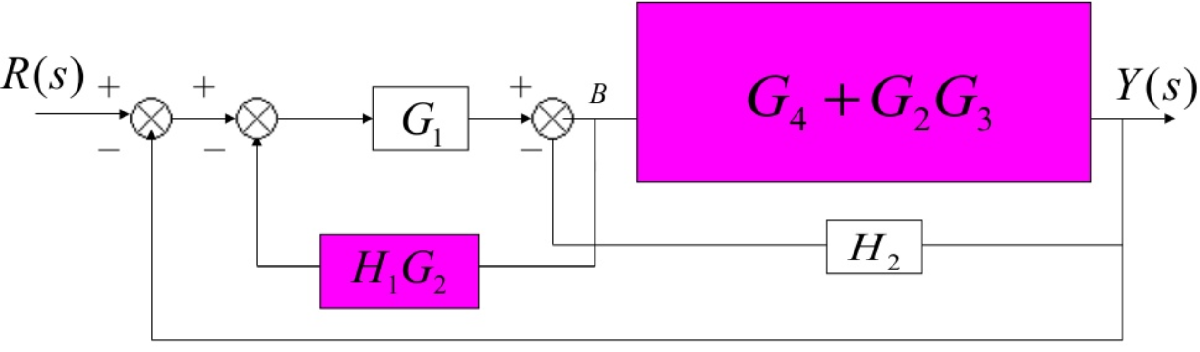

Move pickoff point $B$ to the other side of the $G_4+G_2G_3$ block.

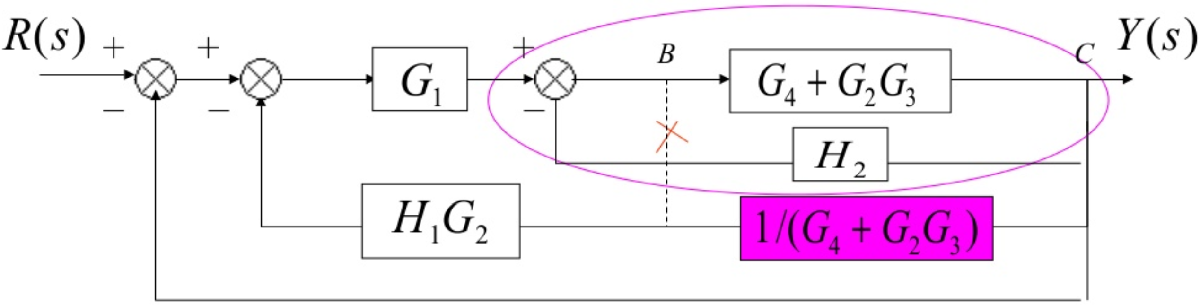

Collapse the feedbacklook circled above:

Method 1 (Checking hand calculations)

clear
syms G_1 G_2 G_3 G_4 H_1 H_2
G_FB1=(G_4+G_2*G_3)/(1+(G_4+G_2*G_3)*H_2)

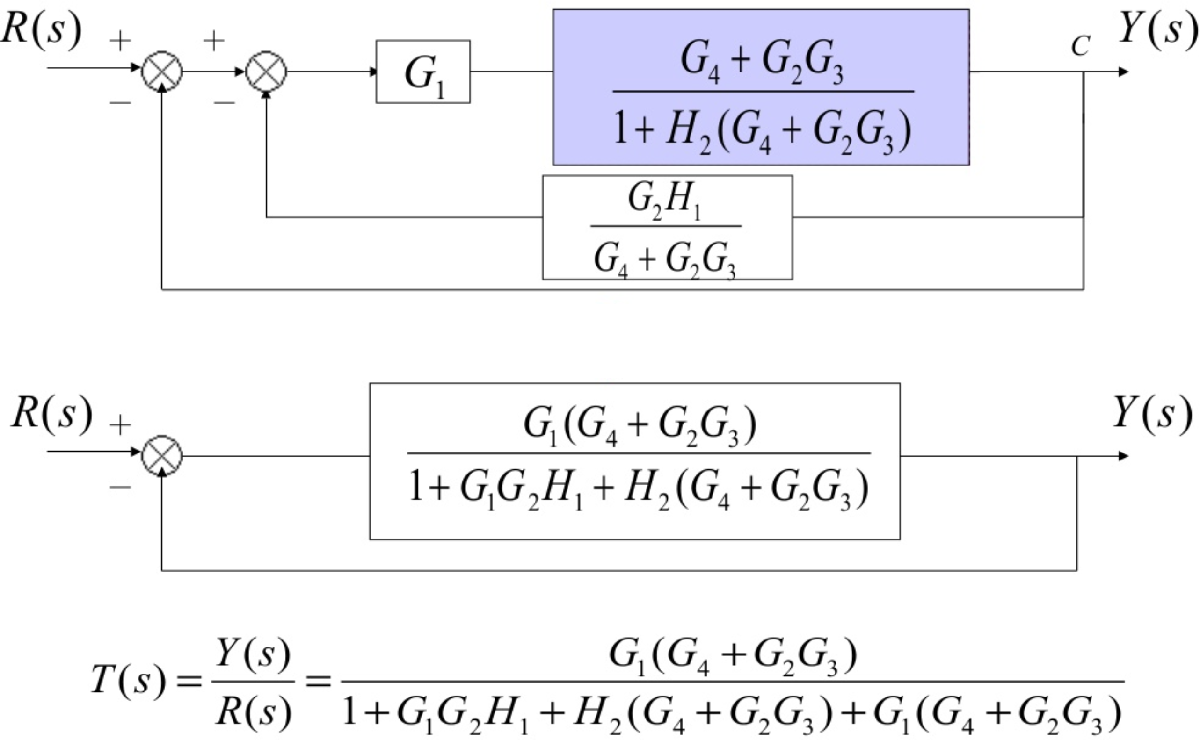

Collapsing the inner feedback look you get:

G_FB2=G_1*G_FB1/(1+G_1*G_FB1*(G_2*H_1)/(G_4+G_2*G_3))
G_2FB=collect(G_FB2)
G_cl=G_FB2/(1+G_FB2)
G_cl=collect(G_cl)

**Method 2:**

Assign variables $X_1, X_2, X_3$ to the outputs of the first 3 summing junctions from left to right

syms R G_1 G_2 G_3 G_4 H_1 H_2 Y X_1 X_2 X_3
eq1=X_1==R-Y
eq2=X_2==X_1-G_2*H_1*X_3
eq3=X_3==G_1*X_2-H_2*Y
eq4=Y==G_2*G_3*X_3+G_4*X_3
BDsoln=solve([eq1,eq2,eq3,eq4],[X_1,X_2,X_3,Y])
G_cl2=BDsoln.Y/R
%[A,B]=equationsToMatrix([eq1,eq2,eq3,eq4],[X_1,X_2,X_3,X_4])
collect(G_cl-G_cl2)